clc
clear
close all

## Get the data

Talb = readtable('C:\Users\floda\Google Drive\NTNU\MasterThesis\Hindcast\TalbotHsTpVDir8221.csv');
TalbMat=table2array(Talb(:,4:9));
TalbVD=TalbMat(:,1);
TalbV=TalbMat(:,2);
TalbHs=TalbMat(:,3);
TalbTp=TalbMat(:,6);
TalbWD=TalbMat(:,5);

TalbVD=TalbVD+180;
TalbWD=TalbWD+180;
years=39;

HsMean=mean(TalbHs)

HsMean = 0.6872

TpMean=mean(TalbTp)

TpMean = 8.7738

WindMean=mean(TalbV)

WindMean = 6.4045

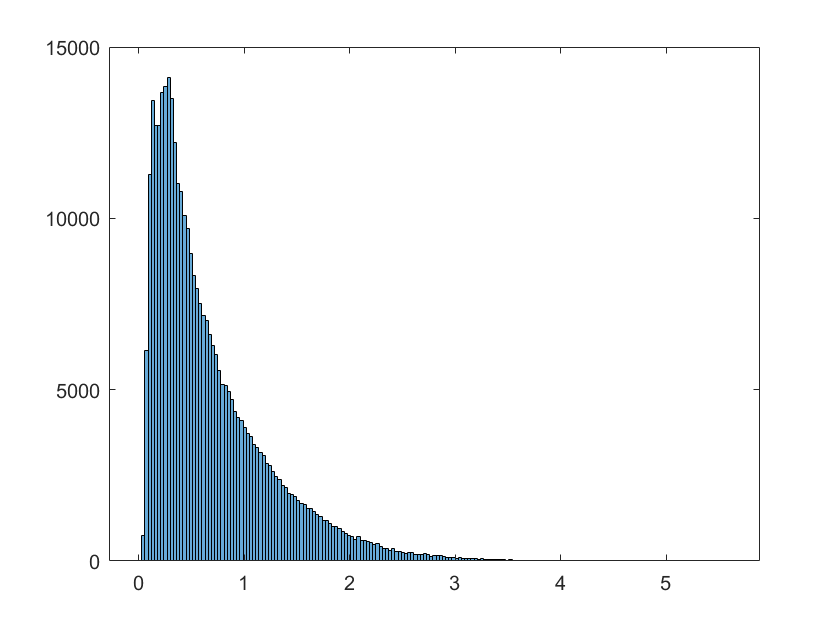


histogram(TalbHs)

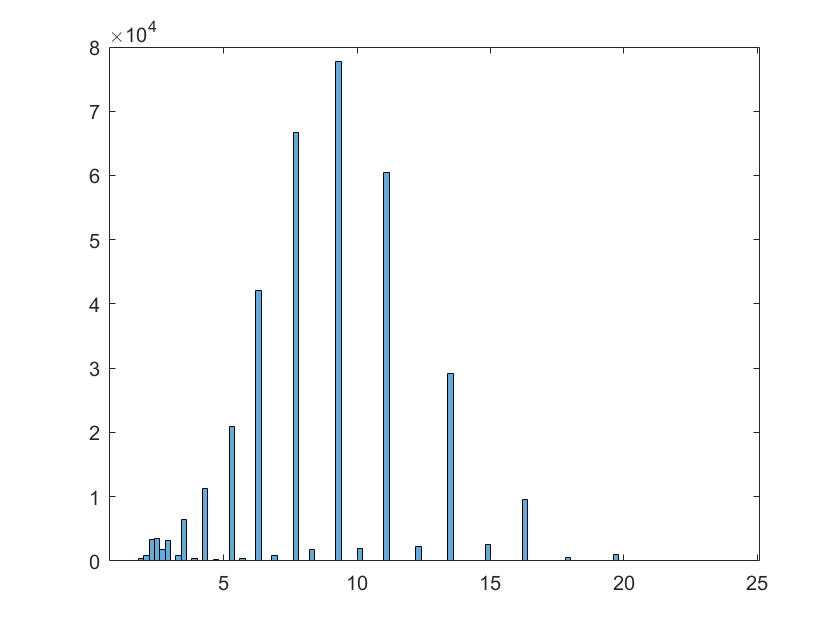

histogram(TalbTp)

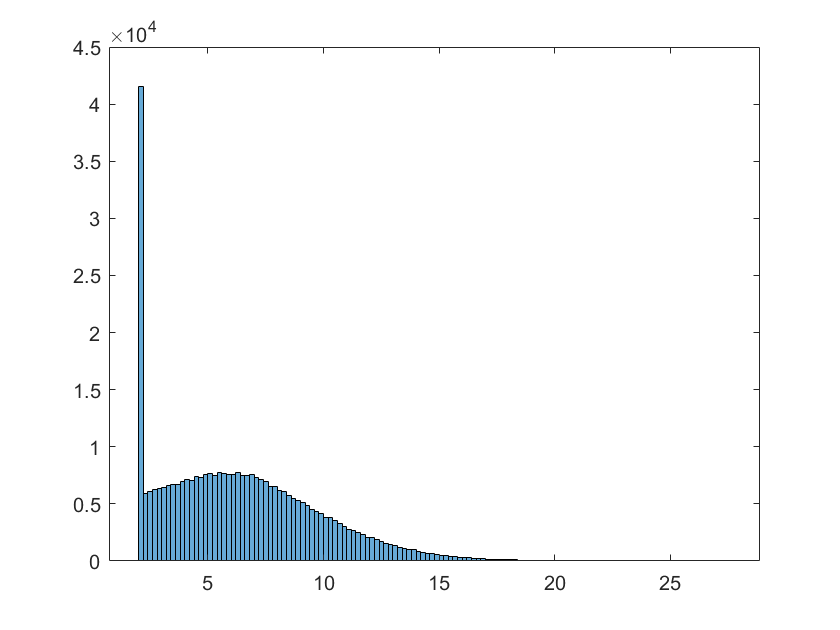

histogram(TalbV)


min(TalbTp)

ans = 1.8260

[maxHs,loc]=max(TalbHs)

maxHs = 5.5820

loc = 70717

TalbTp(loc)

ans = 13.5129

TalbV(loc)

ans = 27.4014

## Finding a likely max

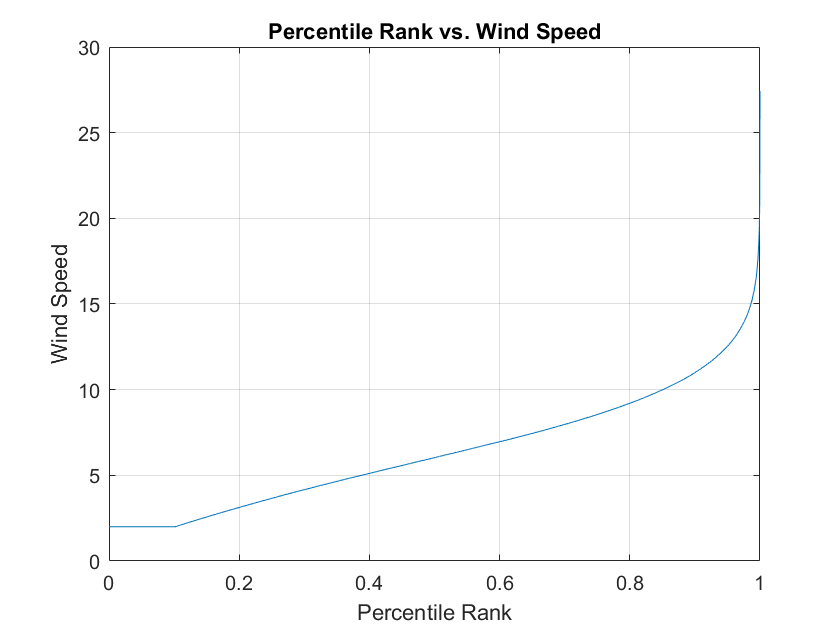

% Sort the wind data in ascending order
sortedData = sort(TalbV);

% Calculate the percentile rank for each data point
N = numel(sortedData);
percentileRank = ((1:N) - 0.5) / N;

% Plot the percentile rank against the data values
plot(percentileRank, sortedData);
xlabel('Percentile Rank');
ylabel('Wind Speed');
title('Percentile Rank vs. Wind Speed');
grid on;


% Identify a suitable threshold based on the plot
thresholdPercentileRank = 0.99;
thresholdValue = sortedData(ceil(thresholdPercentileRank * N));

% Calculate the percentage of wind speeds greater than 14
indices = find(TalbV > 14);
percentV14 = length(indices) / length(TalbV) * 100

percentV14 = 2.3933

% Hs3 = find(TalbHs>1);
% nuHs3 = length(Hs3);
% per3 = nuHs3/length(TalbHs)*100

### Scatter Table

HsTp=[TalbHs,TalbTp];
HsTab=0:0.3:9;
TpTab=0:25;
Scat=zeros(length(HsTab)-1,length(TpTab)-1);

for i=1:length(HsTp)
    for k=1:length(HsTab)-1
        for j=1:length(TpTab)-1
            if (HsTab(k) <= HsTp(i,1)) && (HsTp(i,1)< HsTab(k+1)) && (TpTab(j) <= HsTp(i,2)) && (HsTp(i,2)< TpTab(j+1))
                Scat(k,j)=Scat(k,j)+1;
            end
        end
    end
end
Scat=Scat/length(HsTp)*100;
Scat=flip(Scat);

xlswrite('Scat39.xlsx',Scat);



### Monthly Dist Hs

for i=0:9
    TalbHs((18937+i*35064-i*24):(18960+i*35064-i*24))=[];
end
HsJan=zeros(744,years);
HsFeb=zeros(672,years);
HsMar=zeros(744,years);
HsAp=zeros(720,years);
HsMay=zeros(744,years);
HsJun=zeros(720,years);
HsJul=zeros(744,years);
HsAug=zeros(744,years);
HsSep=zeros(720,years);
HsOct=zeros(744,years);
HsNov=zeros(720,years);
HsDec=zeros(744,years);

for a=0:(years-1)
    HsJan(:,a+1)=TalbHs((1+a*8760):(744+a*8760));
    HsFeb(:,a+1)=TalbHs((745+a*8760):(1416+a*8760));
    HsMar(:,a+1)=TalbHs((1417+a*8760):(2160+a*8760));
    HsAp(:,a+1)=TalbHs((2161+a*8760):(2880+a*8760));
    HsMay(:,a+1)=TalbHs((2881+a*8760):(3624+a*8760));
    HsJun(:,a+1)=TalbHs((3625+a*8760):(4344+a*8760));
    HsJul(:,a+1)=TalbHs((4345+a*8760):(5088+a*8760));
    HsAug(:,a+1)=TalbHs((5089+a*8760):(5832+a*8760));
    HsSep(:,a+1)=TalbHs((5833+a*8760):(6552+a*8760));
    HsOct(:,a+1)=TalbHs((6553+a*8760):(7296+a*8760));
    HsNov(:,a+1)=TalbHs((7297+a*8760):(8016+a*8760));
    HsDec(:,a+1)=TalbHs((8017+a*8760):(8760+a*8760));
end

HsYear31=cat(3,HsJan,HsMar,HsMay,HsJul,HsAug,HsOct,HsDec);
HsYear30=cat(3,HsAp,HsJun,HsSep,HsNov);

Hs_3h_31=zeros(1,7);
Hs_3h_30=zeros(1,4);
Hs_3h_Feb=zeros(1,1);
Hs_6h_31=zeros(1,7);
Hs_6h_30=zeros(1,4);
Hs_6h_Feb=zeros(1,1);
Hs_12h_31=zeros(1,7);
Hs_12h_30=zeros(1,4);
Hs_12h_Feb=zeros(1,1);
Hs_24h_31=zeros(1,7);
Hs_24h_30=zeros(1,4);
Hs_24h_Feb=zeros(1,1);
Hs_48h_31=zeros(1,7);
Hs_48h_30=zeros(1,4);
Hs_48h_Feb=zeros(1,1);
Hs_72h_31=zeros(1,7);
Hs_72h_30=zeros(1,4);
Hs_72h_Feb=zeros(1,1);

lim=0.8;
for y=1:7
    for i=1:(length(HsJan)-2)
        for k=1:years
            Hs3=zeros(1,3);
            for b=1:3
                if HsYear31(i+b-1,k,y) < lim
                    Hs3(b)=1;
                end
            end
            if all(Hs3 == 1)
                Hs_3h_31(y)=Hs_3h_31(y)+1;
            end
        end
    end
end
for y=1:7
    for i=1:(length(HsJan)-5)
        for k=1:years
            Hs6=zeros(1,6);
            for b=1:6
                if HsYear31(i+b-1,k,y) < lim
                    Hs6(b)=1;
                end
            end
            if all(Hs6 == 1)
                Hs_6h_31(y)=Hs_6h_31(y)+1;
            end
        end
    end
end

for y=1:7
    for i=1:(length(HsJan)-11)
        for k=1:years
            Hs12=zeros(1,12);
            for b=1:12
                if HsYear31(i+b-1,k,y) < lim
                    Hs12(b)=1;
                end
            end
            if all(Hs12 == 1)
                Hs_12h_31(y)=Hs_12h_31(y)+1;
            end
        end
    end
end

for y=1:7
    for i=1:(length(HsJan)-23)
        for k=1:years
            Hs24=zeros(1,24);
            for b=1:24
                if HsYear31(i+b-1,k,y) < lim
                    Hs24(b)=1;
                end
            end
            if all(Hs24 == 1)
                Hs_24h_31(y)=Hs_24h_31(y)+1;
            end
        end
    end
end

for y=1:7
    for i=1:(length(HsJan)-47)
        for k=1:years
            Hs48=zeros(1,48);
            for b=1:48
                if HsYear31(i+b-1,k,y) < lim
                    Hs48(b)=1;
                end
            end
            if all(Hs48 == 1)
                Hs_48h_31(y)=Hs_48h_31(y)+1;
            end
        end
    end
end

for y=1:7
    for i=1:(length(HsJan)-71)
        for k=1:years
            Hs72=zeros(1,72);
            for b=1:72
                if HsYear31(i+b-1,k,y) < lim
                    Hs72(b)=1;
                end
            end
            if all(Hs72 == 1)
                Hs_72h_31(y)=Hs_72h_31(y)+1;
            end
        end
    end
end

for y=1:4
    for i=1:(length(HsAp)-2)
        for k=1:years
            Hs3=zeros(1,3);
            for b=1:3
                if HsYear30(i+b-1,k,y) < lim
                    Hs3(b)=1;
                end
            end
            if all(Hs3 == 1)
                Hs_3h_30(y)=Hs_3h_30(y)+1;
            end
        end
    end
end

for y=1:4
    for i=1:(length(HsAp)-5)
        for k=1:years
            Hs6=zeros(1,6);
            for b=1:6
                if HsYear30(i+b-1,k,y) < lim
                    Hs6(b)=1;
                end
            end
            if all(Hs6 == 1)
                Hs_6h_30(y)=Hs_6h_30(y)+1;
            end
        end
    end
end

for y=1:4
    for i=1:(length(HsAp)-11)
        for k=1:years
            Hs12=zeros(1,12);
            for b=1:12
                if HsYear30(i+b-1,k,y) < lim
                    Hs12(b)=1;
                end
            end
            if all(Hs12 == 1)
                Hs_12h_30(y)=Hs_12h_30(y)+1;
            end
        end
    end
end

for y=1:4
    for i=1:(length(HsAp)-23)
        for k=1:years
            Hs24=zeros(1,24);
            for b=1:24
                if HsYear30(i+b-1,k,y) < lim
                    Hs24(b)=1;
                end
            end
            if all(Hs24 == 1)
                Hs_24h_30(y)=Hs_24h_30(y)+1;
            end
        end
    end
end

for y=1:4
    for i=1:(length(HsAp)-47)
        for k=1:years
            Hs48=zeros(1,48);
            for b=1:48
                if HsYear30(i+b-1,k,y) < lim
                    Hs48(b)=1;
                end
            end
            if all(Hs48 == 1)
                Hs_48h_30(y)=Hs_48h_30(y)+1;
            end
        end
    end
end

for y=1:4
    for i=1:(length(HsAp)-71)
        for k=1:years
            Hs72=zeros(1,72);
            for b=1:72
                if HsYear30(i+b-1,k,y) < lim
                    Hs72(b)=1;
                end
            end
            if all(Hs72 == 1)
                Hs_72h_30(y)=Hs_72h_30(y)+1;
            end
        end
    end
end


for i=1:(length(HsFeb)-2)
    for k=1:years
        Hs3=zeros(1,3);
        for b=1:3
            if HsFeb(i+b-1,k) < lim
                Hs3(b)=1;
            end
        end
        if all(Hs3 == 1)
            Hs_3h_Feb=Hs_3h_Feb+1;
        end
    end
end


for i=1:(length(HsFeb)-5)
    for k=1:years
        Hs6=zeros(1,6);
        for b=1:6
            if HsFeb(i+b-1,k) < lim
                Hs6(b)=1;
            end
        end
        if all(Hs6 == 1)
            Hs_6h_Feb=Hs_6h_Feb+1;
        end
    end
end



for i=1:(length(HsFeb)-11)
    for k=1:years
        Hs12=zeros(1,12);
        for b=1:12
            if HsFeb(i+b-1,k) < lim
                Hs12(b)=1;
            end
        end
        if all(Hs12 == 1)
            Hs_12h_Feb=Hs_12h_Feb+1;
        end
    end
end



for i=1:(length(HsFeb)-23)
    for k=1:years
        Hs24=zeros(1,24);
        for b=1:24
            if HsFeb(i+b-1,k) < lim
                Hs24(b)=1;
            end
        end
        if all(Hs24 == 1)
            Hs_24h_Feb=Hs_24h_Feb+1;
        end
    end
end


for i=1:(length(HsFeb)-47)
    for k=1:years
        Hs48=zeros(1,48);
        for b=1:48
            if HsFeb(i+b-1,k) < lim
                Hs48(b)=1;
            end
        end
        if all(Hs48 == 1)
            Hs_48h_Feb=Hs_48h_Feb+1;
        end
    end
end



for i=1:(length(HsFeb)-71)
    for k=1:years
        Hs72=zeros(1,72);
        for b=1:72
            if HsFeb(i+b-1,k) < lim
                Hs72(b)=1;
            end
        end
        if all(Hs72 == 1)
            Hs_72h_Feb=Hs_72h_Feb+1;
        end
    end
end



Hs_3h_31=Hs_3h_31/(years*(length(HsJan)-2))*100;
Hs_3h_30=Hs_3h_30/(years*(length(HsAp)-2))*100;
Hs_3h_Feb=Hs_3h_Feb/(years*(length(HsFeb)-2))*100;

Hs_6h_31=Hs_6h_31/(years*(length(HsJan)-5))*100;
Hs_6h_30=Hs_6h_30/(years*(length(HsAp)-5))*100;
Hs_6h_Feb=Hs_6h_Feb/(years*(length(HsFeb)-5))*100;

Hs_12h_31=Hs_12h_31/(years*(length(HsJan)-11))*100;
Hs_12h_30=Hs_12h_30/(years*(length(HsAp)-11))*100;
Hs_12h_Feb=Hs_12h_Feb/(years*(length(HsFeb)-11))*100;

Hs_24h_31=Hs_24h_31/(years*(length(HsJan)-23))*100;
Hs_24h_30=Hs_24h_30/(years*(length(HsAp)-23))*100;
Hs_24h_Feb=Hs_24h_Feb/(years*(length(HsFeb)-23))*100;

Hs_48h_31=Hs_48h_31/(years*(length(HsJan)-47))*100;
Hs_48h_30=Hs_48h_30/(years*(length(HsAp)-47))*100;
Hs_48h_Feb=Hs_48h_Feb/(years*(length(HsFeb)-47))*100;

Hs_72h_31=Hs_72h_31/(years*(length(HsJan)-71))*100;
Hs_72h_30=Hs_72h_30/(years*(length(HsAp)-71))*100;
Hs_72h_Feb=Hs_72h_Feb/(years*(length(HsFeb)-71))*100;

Hs_lim=[Hs_3h_31(1),Hs_3h_Feb,Hs_3h_31(2),Hs_3h_30(1),Hs_3h_31(3),Hs_3h_30(2),Hs_3h_31(4),Hs_3h_31(5),Hs_3h_30(3),Hs_3h_31(6),Hs_3h_30(4),Hs_3h_31(7); ...
    Hs_6h_31(1),Hs_6h_Feb,Hs_6h_31(2),Hs_6h_30(1),Hs_6h_31(3),Hs_6h_30(2),Hs_6h_31(4),Hs_6h_31(5),Hs_6h_30(3),Hs_6h_31(6),Hs_6h_30(4),Hs_6h_31(7); ...
    Hs_12h_31(1),Hs_12h_Feb,Hs_12h_31(2),Hs_12h_30(1),Hs_12h_31(3),Hs_12h_30(2),Hs_12h_31(4),Hs_12h_31(5),Hs_12h_30(3),Hs_12h_31(6),Hs_12h_30(4),Hs_12h_31(7);...
    Hs_24h_31(1),Hs_24h_Feb,Hs_24h_31(2),Hs_24h_30(1),Hs_24h_31(3),Hs_24h_30(2),Hs_24h_31(4),Hs_24h_31(5),Hs_24h_30(3),Hs_24h_31(6),Hs_24h_30(4),Hs_24h_31(7);...
    Hs_48h_31(1),Hs_48h_Feb,Hs_48h_31(2),Hs_48h_30(1),Hs_48h_31(3),Hs_48h_30(2),Hs_48h_31(4),Hs_48h_31(5),Hs_48h_30(3),Hs_48h_31(6),Hs_48h_30(4),Hs_48h_31(7);...
    Hs_72h_31(1),Hs_72h_Feb,Hs_72h_31(2),Hs_72h_30(1),Hs_72h_31(3),Hs_72h_30(2),Hs_72h_31(4),Hs_72h_31(5),Hs_72h_30(3),Hs_72h_31(6),Hs_72h_30(4),Hs_72h_31(7)];

xlswrite('Hs_lim.xlsx',Hs_lim);

### Roses

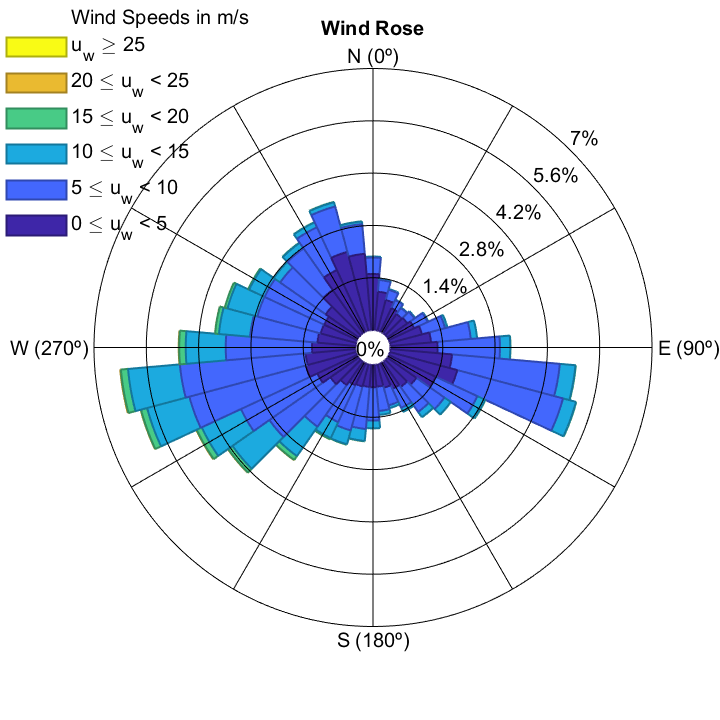

%if not working in command window: addpath 'C:\windrose'
% All the wind rose options into a cell array, so function call can be simplified
addpath 'C:\windrose'
Properties = {'anglenorth',0,'angleeast',90,'labels',{'N (0º)','E (90º)','S (180º)','W (270º)'},'freqlabelangle',45};
[figure_handle,count,speeds,directions,Table,Others] = WindRose(TalbVD,TalbV,Properties);


countWindSum=sum(count,2);
combi=[directions,countWindSum];

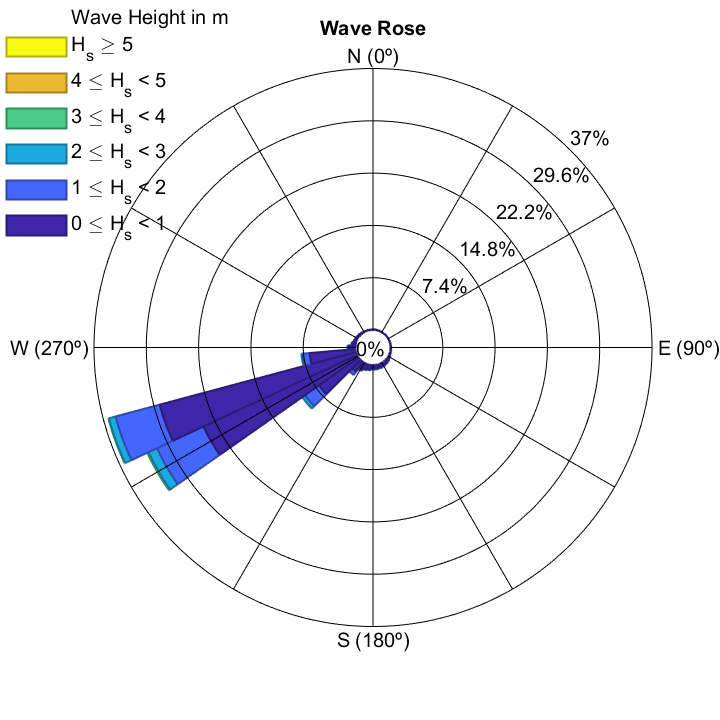

[figure_handleW,countW,speedsW,directionsW,TableW,OthersW] = WaveRose(TalbWD,TalbHs,Properties);

### Monthly Wind and Period

for i=0:9
    TalbV((18937+i*35064-i*24):(18960+i*35064-i*24))=[];
end
VJan=zeros(744,years);
VFeb=zeros(672,years);
VMar=zeros(744,years);
VAp=zeros(720,years);
VMay=zeros(744,years);
VJun=zeros(720,years);
VJul=zeros(744,years);
VAug=zeros(744,years);
VSep=zeros(720,years);
VOct=zeros(744,years);
VNov=zeros(720,years);
VDec=zeros(744,years);

for a=0:(years-1)
    VJan(:,a+1)=TalbV((1+a*8760):(744+a*8760));
    VFeb(:,a+1)=TalbV((745+a*8760):(1416+a*8760));
    VMar(:,a+1)=TalbV((1417+a*8760):(2160+a*8760));
    VAp(:,a+1)=TalbV((2161+a*8760):(2880+a*8760));
    VMay(:,a+1)=TalbV((2881+a*8760):(3624+a*8760));
    VJun(:,a+1)=TalbV((3625+a*8760):(4344+a*8760));
    VJul(:,a+1)=TalbV((4345+a*8760):(5088+a*8760));
    VAug(:,a+1)=TalbV((5089+a*8760):(5832+a*8760));
    VSep(:,a+1)=TalbV((5833+a*8760):(6552+a*8760));
    VOct(:,a+1)=TalbV((6553+a*8760):(7296+a*8760));
    VNov(:,a+1)=TalbV((7297+a*8760):(8016+a*8760));
    VDec(:,a+1)=TalbV((8017+a*8760):(8760+a*8760));
end

for i=0:9
    TalbTp((18937+i*35064-i*24):(18960+i*35064-i*24))=[];
end
TpJan=zeros(744,years);
TpFeb=zeros(672,years);
TpMar=zeros(744,years);
TpAp=zeros(720,years);
TpMay=zeros(744,years);
TpJun=zeros(720,years);
TpJul=zeros(744,years);
TpAug=zeros(744,years);
TpSep=zeros(720,years);
TpOct=zeros(744,years);
TpNov=zeros(720,years);
TpDec=zeros(744,years);

for a=0:(years-1)
    TpJan(:,a+1)=TalbTp((1+a*8760):(744+a*8760));
    TpFeb(:,a+1)=TalbTp((745+a*8760):(1416+a*8760));
    TpMar(:,a+1)=TalbTp((1417+a*8760):(2160+a*8760));
    TpAp(:,a+1)=TalbTp((2161+a*8760):(2880+a*8760));
    TpMay(:,a+1)=TalbTp((2881+a*8760):(3624+a*8760));
    TpJun(:,a+1)=TalbTp((3625+a*8760):(4344+a*8760));
    TpJul(:,a+1)=TalbTp((4345+a*8760):(5088+a*8760));
    TpAug(:,a+1)=TalbTp((5089+a*8760):(5832+a*8760));
    TpSep(:,a+1)=TalbTp((5833+a*8760):(6552+a*8760));
    TpOct(:,a+1)=TalbTp((6553+a*8760):(7296+a*8760));
    TpNov(:,a+1)=TalbTp((7297+a*8760):(8016+a*8760));
    TpDec(:,a+1)=TalbTp((8017+a*8760):(8760+a*8760));
end

### Monthly max

HsJanMax=max(HsJan);
HsFebMax=max(HsFeb);
HsMarMax=max(HsMar);
HsApMax=max(HsAp);
HsMayMax=max(HsMay);
HsJunMax=max(HsJun);
HsJulMax=max(HsJul);
HsAugMax=max(HsAug);
HsSepMax=max(HsSep);
HsOctMax=max(HsOct);
HsNovMax=max(HsNov);
HsDecMax=max(HsDec);

MonMaxHs=[HsJanMax;HsFebMax;HsMarMax;HsApMax;HsMayMax;HsJunMax;HsJulMax;HsAugMax;HsSepMax;HsOctMax;HsNovMax;HsDecMax];

AnMaxHs=max(MonMaxHs);

VJanMax=max(VJan);
VFebMax=max(VFeb);
VMarMax=max(VMar);
VApMax=max(VAp);
VMayMax=max(VMay);
VJunMax=max(VJun);
VJulMax=max(VJul);
VAugMax=max(VAug);
VSepMax=max(VSep);
VOctMax=max(VOct);
VNovMax=max(VNov);
VDecMax=max(VDec);

MonMaxV=[VJanMax;VFebMax;VMarMax;VApMax;VMayMax;VJunMax;VJulMax;VAugMax;VSepMax;VOctMax;VNovMax;VDecMax];

AnMaxV=max(MonMaxV);

TpJanMax=max(TpJan);
TpFebMax=max(TpFeb);
TpMarMax=max(TpMar);
TpApMax=max(TpAp);
TpMayMax=max(TpMay);
TpJunMax=max(TpJun);
TpJulMax=max(TpJul);
TpAugMax=max(TpAug);
TpSepMax=max(TpSep);
TpOctMax=max(TpOct);
TpNovMax=max(TpNov);
TpDecMax=max(TpDec);

MonMaxTp=[TpJanMax;TpFebMax;TpMarMax;TpApMax;TpMayMax;TpJunMax;TpJulMax;TpAugMax;TpSepMax;TpOctMax;TpNovMax;TpDecMax];

AnMaxTp=max(MonMaxTp);

### Wind wave comb

AnHsTpV=[TalbHs,TalbTp,TalbV];

TpAnMax=zeros(5,years);
HsAnMax=zeros(5,years);
for l=1:years
    AnData=AnHsTpV((1+(l-1)*8760):(l*8760),:);

    V6loc=find(AnData(:,3) > 5.5 & AnData(:,3) <6.5);
    V8loc=find(AnData(:,3) > 7.5 & AnData(:,3) <8.5);
    V10loc=find(AnData(:,3) > 9.5 & AnData(:,3) <10.5);
    V12loc=find(AnData(:,3) > 11.5 & AnData(:,3) <12.5);
    V14loc=find(AnData(:,3) > 13.5 & AnData(:,3) <14.5);

    HsV6=AnData(V6loc,1);
    HsV8=AnData(V8loc,1);
    HsV10=AnData(V10loc,1);
    HsV12=AnData(V12loc,1);
    HsV14=AnData(V14loc,1);

    TpV6=AnData(V6loc,2);
    TpV8=AnData(V8loc,2);
    TpV10=AnData(V10loc,2);
    TpV12=AnData(V12loc,2);
    TpV14=AnData(V14loc,2);

    [HsAnMax(1,l),loc6]=max(HsV6);
    [HsAnMax(2,l),loc8]=max(HsV8);
    [HsAnMax(3,l),loc10]=max(HsV10);
    [HsAnMax(4,l),loc12]=max(HsV12);
    [HsAnMax(5,l),loc14]=max(HsV14);

    TpAnMax(1,l)=TpV6(loc6);
    TpAnMax(2,l)=TpV8(loc8);
    TpAnMax(3,l)=TpV10(loc10);
    TpAnMax(4,l)=TpV12(loc12);
    TpAnMax(5,l)=TpV14(loc14);
end
% meanHsMax=mean(HsAnMax,2)';
% meanTpMax=mean(TpAnMax,2)';
% ConditionsA=[6 8 10 12 14;meanHsMax;meanTpMax]'


% 
% V6loc=find(TalbV > 5.5 & TalbV <6.5);
% V8loc=find(TalbV > 7.5 & TalbV <8.5);
% V10loc=find(TalbV > 9.5 & TalbV <10.5);
% V12loc=find(TalbV > 11.5 & TalbV <12.5);
% V14loc=find(TalbV > 13.5 & TalbV <14.5);
% 
% HsV6=TalbHs(V6loc);
% HsV8=TalbHs(V8loc);
% HsV10=TalbHs(V10loc);
% HsV12=TalbHs(V12loc);
% HsV14=TalbHs(V14loc);
% 
% TpV6=TalbTp(V6loc);
% TpV8=TalbTp(V8loc);
% TpV10=TalbTp(V10loc);
% TpV12=TalbTp(V12loc);
% TpV14=TalbTp(V14loc);
% 
% [Hsmax6,loc6]=max(HsV6);
% [Hsmax8,loc8]=max(HsV8);
% [Hsmax10,loc10]=max(HsV10);
% [Hsmax12,loc12]=max(HsV12);
% [Hsmax14,loc14]=max(HsV14);
% 
% Tpmax6=TpV6(loc6);
% Tpmax8=TpV8(loc8);
% Tpmax10=TpV10(loc10);
% Tpmax12=TpV12(loc12);
% Tpmax14=TpV14(loc14);
% 
% ConditionsA=[6 8 10 12 14;Hsmax6 Hsmax8 Hsmax10 Hsmax12 Hsmax14;Tpmax6 Tpmax8 Tpmax10 Tpmax12 Tpmax14]'


HsTp6=[HsV6,TpV6];
HsTp8=[HsV8,TpV8];
HsTp10=[HsV10,TpV10];
HsTp12=[HsV12,TpV12];
HsTp14=[HsV14,TpV14];

HsTabDet=round(0:0.1:9,1);
TpTabDet=0:0.1:25;
ScatDet=zeros(length(HsTabDet)-1,length(TpTabDet)-1);

trsh=0.65;
tresh=1.35;

for i=1:length(HsTp6)
    for k=1:length(HsTabDet)-1
        for j=1:length(TpTabDet)-1
            if (HsTabDet(k) <= HsTp6(i,1)) && (HsTp6(i,1)< HsTabDet(k+1)) && (TpTabDet(j) <= HsTp6(i,2)) && (HsTp6(i,2)< TpTabDet(j+1))
                ScatDet(k,j)=ScatDet(k,j)+1;
            end
        end
    end
end

ScatDet=ScatDet/length(HsTp6)*100;
[row, col] = find(ismember(ScatDet, max(ScatDet(:))));
Prob6=max(ScatDet(:));
Hs6prob=HsTabDet(row);
Tp6prob=TpTabDet(col);

HsTp6mean=mean(HsTp6);

Hs6Min30=round(trsh*HsTp6mean(1),1);
Hs6Pl30=round(tresh*HsTp6mean(1),1);
Hs6MinPos=find(HsTabDet==Hs6Min30);
Hs6PlPos=find(HsTabDet==Hs6Pl30);
Sc30_6=ScatDet(Hs6MinPos:Hs6PlPos,:);
Prob30_6=sum(Sc30_6(:))

Prob30_6 = 52.3242


Tp6_m35_loc=find(HsV6 > Hs6Min30*0.8 & HsV6 <Hs6Min30*1.2);
Tp6_m35=TpV6(Tp6_m35_loc);
Tp6_m35_mean=mean(Tp6_m35);

Tp6_p35_loc=find(HsV6 > Hs6Pl30*0.8 & HsV6 <Hs6Pl30*1.2);
Tp6_p35=TpV6(Tp6_p35_loc);
Tp6_p35_mean=mean(Tp6_p35);


Tp6Pl35=round(tresh*HsTp6mean(2),1);
Hs6_p35_loc=find(TpV6 > Tp6Pl35*0.8 & TpV6 <Tp6Pl35*1.2);
Hs6_p35=HsV6(Hs6_p35_loc);
Hs6_p35_mean=mean(Hs6_p35);



ScatDet=zeros(length(HsTabDet)-1,length(TpTabDet)-1);
for i=1:length(HsTp8)
    for k=1:length(HsTabDet)-1
        for j=1:length(TpTabDet)-1
            if (HsTabDet(k) <= HsTp8(i,1)) && (HsTp8(i,1)< HsTabDet(k+1)) && (TpTabDet(j) <= HsTp8(i,2)) && (HsTp8(i,2)< TpTabDet(j+1))
                ScatDet(k,j)=ScatDet(k,j)+1;
            end
        end
    end
end

ScatDet=ScatDet/length(HsTp8)*100;
[row, col] = find(ismember(ScatDet, max(ScatDet(:))));
Prob8=max(ScatDet(:));
Hs8prob=HsTabDet(row(1));
Tp8prob=TpTabDet(col(1));

HsTp8mean=mean(HsTp8);

Hs8Min30=round(trsh*HsTp8mean(1),1);
Hs8Pl30=round(tresh*HsTp8mean(1),1);
Hs8MinPos=find(HsTabDet==Hs8Min30);
Hs8PlPos=find(HsTabDet==Hs8Pl30);
Sc30_8=ScatDet(Hs8MinPos:Hs8PlPos,:);
Prob30_8=sum(Sc30_8(:))

Prob30_8 = 54.6135


Tp8_m35_loc=find(HsV8 > Hs8Min30*0.8 & HsV8 <Hs8Min30*1.2);
Tp8_m35=TpV8(Tp8_m35_loc);
Tp8_m35_mean=mean(Tp8_m35);

Tp8_p35_loc=find(HsV8 > Hs8Pl30*0.8 & HsV8 <Hs8Pl30*1.2);
Tp8_p35=TpV8(Tp8_p35_loc);
Tp8_p35_mean=mean(Tp8_p35);

Tp8Pl35=round(tresh*HsTp8mean(2),1);
Hs8_p35_loc=find(TpV8 > Tp8Pl35*0.8 & TpV8 <Tp8Pl35*1.2);
Hs8_p35=HsV8(Hs8_p35_loc);
Hs8_p35_mean=mean(Hs8_p35);


ScatDet=zeros(length(HsTabDet)-1,length(TpTabDet)-1);
for i=1:length(HsTp10)
    for k=1:length(HsTabDet)-1
        for j=1:length(TpTabDet)-1
            if (HsTabDet(k) <= HsTp10(i,1)) && (HsTp10(i,1)< HsTabDet(k+1)) && (TpTabDet(j) <= HsTp10(i,2)) && (HsTp10(i,2)< TpTabDet(j+1))
                ScatDet(k,j)=ScatDet(k,j)+1;
            end
        end
    end
end
ScatDet=ScatDet/length(HsTp10)*100;
[row, col] = find(ismember(ScatDet, max(ScatDet(:))));
Prob10=max(ScatDet(:));
Hs10prob=HsTabDet(row);
Tp10prob=TpTabDet(col);

HsTp10mean=mean(HsTp10);

Hs10Min30=round(trsh*HsTp10mean(1),1);
Hs10Pl30=round(tresh*HsTp10mean(1),1);
Hs10MinPos=find(HsTabDet==Hs10Min30);
Hs10PlPos=find(HsTabDet==Hs10Pl30);
Sc30_10=ScatDet(Hs10MinPos:Hs10PlPos,:);
Prob30_10=sum(Sc30_10(:))

Prob30_10 = 70.9619


Tp10_m35_loc=find(HsV10 > Hs10Min30*0.8 & HsV10 <Hs10Min30*1.2);
Tp10_m35=TpV10(Tp10_m35_loc);
Tp10_m35_mean=mean(Tp10_m35);

Tp10_p35_loc=find(HsV10 > Hs10Pl30*0.8 & HsV10 <Hs10Pl30*1.2);
Tp10_p35=TpV10(Tp10_p35_loc);
Tp10_p35_mean=mean(Tp10_p35);

Tp10Pl35=round(tresh*HsTp10mean(2),1);
Hs10_p35_loc=find(TpV10 > Tp10Pl35*0.8 & TpV10 <Tp10Pl35*1.2);
Hs10_p35=HsV10(Hs10_p35_loc);
Hs10_p35_mean=mean(Hs10_p35);


ScatDet=zeros(length(HsTabDet)-1,length(TpTabDet)-1);
for i=1:length(HsTp12)
    for k=1:length(HsTabDet)-1
        for j=1:length(TpTabDet)-1
            if (HsTabDet(k) <= HsTp12(i,1)) && (HsTp12(i,1)< HsTabDet(k+1)) && (TpTabDet(j) <= HsTp12(i,2)) && (HsTp12(i,2)< TpTabDet(j+1))
                ScatDet(k,j)=ScatDet(k,j)+1;
            end
        end
    end
end

ScatDet=ScatDet/length(HsTp12)*100;
[row, col] = find(ismember(ScatDet, max(ScatDet(:))));
Prob12=max(ScatDet(:));
Hs12prob=HsTabDet(row);
Tp12prob=TpTabDet(col);

HsTp12mean=mean(HsTp12);

Hs12Min30=round(trsh*HsTp12mean(1),1);
Hs12Pl30=round(tresh*HsTp12mean(1),1);
Hs12MinPos=find(HsTabDet==Hs12Min30);
Hs12PlPos=find(HsTabDet==Hs12Pl30);
Sc30_12=ScatDet(Hs12MinPos:Hs12PlPos,:);
Prob30_12=sum(Sc30_12(:))

Prob30_12 = 84.3648


Tp12_m35_loc=find(HsV12 > Hs12Min30*0.8 & HsV12 <Hs12Min30*1.2);
Tp12_m35=TpV12(Tp12_m35_loc);
Tp12_m35_mean=mean(Tp12_m35);

Tp12_p35_loc=find(HsV12 > Hs12Pl30*0.8 & HsV12 <Hs12Pl30*1.2);
Tp12_p35=TpV12(Tp12_p35_loc);
Tp12_p35_mean=mean(Tp12_p35);

Tp12Pl35=round(tresh*HsTp12mean(2),1);
Hs12_p35_loc=find(TpV12 > Tp12Pl35*0.8 & TpV12 <Tp12Pl35*1.2);
Hs12_p35=HsV12(Hs12_p35_loc);
Hs12_p35_mean=mean(Hs12_p35);


ScatDet=zeros(length(HsTabDet)-1,length(TpTabDet)-1);
for i=1:length(HsTp14)
    for k=1:length(HsTabDet)-1
        for j=1:length(TpTabDet)-1
            if (HsTabDet(k) <= HsTp14(i,1)) && (HsTp14(i,1)< HsTabDet(k+1)) && (TpTabDet(j) <= HsTp14(i,2)) && (HsTp14(i,2)< TpTabDet(j+1))
                ScatDet(k,j)=ScatDet(k,j)+1;
            end
        end
    end
end

ScatDet=ScatDet/length(HsTp14)*100;
[row, col] = find(ismember(ScatDet, max(ScatDet(:))));
Prob14=max(ScatDet(:));
Hs14prob=HsTabDet(row);
Tp14prob=TpTabDet(col);

HsTp14mean=mean(HsTp14);

Hs14Min30=round(trsh*HsTp14mean(1),1);
Hs14Pl30=round(tresh*HsTp14mean(1),1);
Hs14MinPos=find(HsTabDet==Hs14Min30);
Hs14PlPos=find(HsTabDet==Hs14Pl30);
Sc30_14=ScatDet(Hs14MinPos:Hs14PlPos,:);
Prob30_14=sum(Sc30_14(:))

Prob30_14 = 98.5401


Tp14_m35_loc=find(HsV14 > Hs14Min30*0.8 & HsV14 <Hs14Min30*1.2);
Tp14_m35=TpV14(Tp14_m35_loc);
Tp14_m35_mean=mean(Tp14_m35);

Tp14_p35_loc=find(HsV14 > Hs14Pl30*0.8 & HsV14 <Hs14Pl30*1.2);
Tp14_p35=TpV14(Tp14_p35_loc);
Tp14_p35_mean=mean(Tp14_p35);

Tp14Pl35=round(tresh*HsTp14mean(2),1);
Hs14_p35_loc=find(TpV14 > Tp14Pl35*0.8 & TpV14 <Tp14Pl35*1.2);
Hs14_p35=HsV14(Hs14_p35_loc);
Hs14_p35_mean=mean(Hs14_p35);

ConditionsABC=[6 8 10 12 14;HsTp6mean(1) HsTp8mean(1) HsTp10mean(1) HsTp12mean(1) HsTp14mean(1);HsTp6mean(2) HsTp8mean(2) HsTp10mean(2) HsTp12mean(2) HsTp14mean(2)]'

ConditionsABC =     6.0000    0.5248    8.6688
    8.0000    0.7934    7.5451
   10.0000    1.1865    7.8628
   12.0000    1.6022    8.5966
   14.0000    2.0278    9.1171



ConditionsDEF=[6 8 10 12 14;Hs6Min30 Hs8Min30 Hs10Min30 Hs12Min30 Hs14Min30;Tp6_m35_mean Tp8_m35_mean Tp10_m35_mean Tp12_m35_mean Tp14_m35_mean]'

ConditionsDEF =     6.0000    0.3000    8.7186
    8.0000    0.5000    6.7673
   10.0000    0.8000    6.3761
   12.0000    1.0000    7.3972
   14.0000    1.3000    9.0487



ConditionsGHI=[6 8 10 12 14;Hs6Pl30 Hs8Pl30 Hs10Pl30 Hs12Pl30 Hs14Pl30;Tp6_p35_mean Tp8_p35_mean Tp10_p35_mean Tp12_p35_mean Tp14_p35_mean]'

ConditionsGHI =     6.0000    0.7000    7.4358
    8.0000    1.1000    8.8620
   10.0000    1.6000    9.1361
   12.0000    2.2000   10.0406
   14.0000    2.7000   10.3130



CondiAlt=[6 8 10 12 14;Hs6_p35_mean Hs8_p35_mean Hs10_p35_mean Hs12_p35_mean Hs14_p35_mean;Tp6Pl35 Tp8Pl35 Tp10Pl35 Tp12Pl35 Tp14Pl35]'

CondiAlt =     6.0000    0.5685   11.7000
    8.0000    1.0184   10.2000
   10.0000    1.4112   10.6000
   12.0000    1.9393   11.6000
   14.0000    2.2899   12.3000



CondiHighProb=[6 8 10 12 14;Hs6prob Hs8prob Hs10prob Hs12prob Hs14prob(1);Tp6prob Tp8prob Tp10prob Tp12prob Tp14prob(1);Prob6 Prob8 Prob10 Prob12 Prob14]'

CondiHighProb =     6.0000    0.1000   11.1000    3.2181
    8.0000    0.8000    6.3000    3.3666
   10.0000    1.4000    9.2000    4.9002
   12.0000    1.7000    9.2000    5.8632
   14.0000    1.8000    7.6000    8.7591


## tides

% Tides = readtable('C:\Users\floda\Google Drive\NTNU\MasterThesis\Logistics\Research-Assignment-main\Research-Assignment-main\tide_data.csv');
% %Tides =load('C:\Users\floda\Google Drive\NTNU\MasterThesis\Logistics\Research-Assignment-main\Research-Assignment-main\tide_data.mat');
% 
% TideTime=table2array(Tides(:,1));
% 
% TideHeight=table2array(Tides(:,2));
% 
% xq = 120:60:4828126;
% 
% % Remove duplicates from TideTime
% [TideTime_unique, idx_unique] = unique(TideTime);
% TideHeight_unique = TideHeight(idx_unique);
% 
% % Interpolate using spline
% vq2 = pchip(TideTime_unique, TideHeight_unique, xq);
% 
% % Plot original data and interpolated data
% figure
% plot(TideTime, TideHeight, 'o', xq, vq2, ':.');
% title('Interpolation');
% legend('Original Data', 'Interpolated Data');
% xlabel('Time (min)');
% ylabel('Tide Height (m)');
% 
% MeanTideHeight=mean(TideHeight)
% 
% TideHeightPort=vq2+(11-mean(MeanTideHeight));
% 
% PortMin=min(TideHeightPort)
% PortMax=max(TideHeightPort)
% PortMean=mean(TideHeightPort)

% 
% tides14=TideHeightPort(1:7654);
% tides6=zeros(8760,7);
% xDate=(7654+8759+1416);
% TideHeightPort(xDate:(xDate+23))=[];
% for i=1:7
%     tides6(:,i)=TideHeightPort((7654+((i-1)*8759)):(7654+(i*8759)));
% end
% tides15=tides6(:,1);
% tides16=tides6(:,2);
% tides17=tides6(:,3);
% tides18=tides6(:,4);
% tides19=tides6(:,5);
% tides20=tides6(:,6);
% tides21=tides6(:,7);

% 
% 
% hrslim=0:8760;
% f1=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
% plot(hrslim,TideHeightPort(7654:(7654+8760)))
% xlabel('Time (h)');
% ylabel('Mean Sea Level (m)');
% xlim([0 8760])
% max(TideHeightPort(7654:(7654+8760)))
% min(TideHeightPort(7654:(7654+8760)))
% std(TideHeightPort(7654:(7654+8760)))
% exportgraphics(f1,'TideTimeSeries.pdf')

## 2015

% % Define the start and end dates
% startDate = datetime('2015-01-01 00:00:00');
% endDate = datetime('2015-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time15 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data15 = table(time15', tides15, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data15, 'tide_data_2015.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2016

% % Define the start and end dates
% startDate1 = datetime('2016-01-01 00:00:00');
% endDate1 = datetime('2016-02-28 23:00:00');
% startDate2 = datetime('2016-03-01 00:00:00');
% endDate2 = datetime('2016-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time161 = startDate1:hours(1):endDate1;
% time162 = startDate2:hours(1):endDate2;
% time16 = [time161,time162];
% 
% % Create a table with the datetime and data columns
% data16 = table(time16', tides16, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data16, 'tide_data_2016.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2017

% % Define the start and end dates
% startDate = datetime('2017-01-01 00:00:00');
% endDate = datetime('2017-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time17 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data17 = table(time17', tides17, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data17, 'tide_data_2017.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2018

% % Define the start and end dates
% startDate = datetime('2018-01-01 00:00:00');
% endDate = datetime('2018-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time18 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data18 = table(time18', tides18, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data18, 'tide_data_2018.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2019

% % Define the start and end dates
% startDate = datetime('2019-01-01 00:00:00');
% endDate = datetime('2019-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time19 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data19 = table(time19', tides19, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data19, 'tide_data_2019.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2020

% % Define the start and end dates
% startDate1 = datetime('2020-01-01 00:00:00');
% endDate1 = datetime('2020-02-28 23:00:00');
% startDate2 = datetime('2020-03-01 00:00:00');
% endDate2 = datetime('2020-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time201 = startDate1:hours(1):endDate1;
% time202 = startDate2:hours(1):endDate2;
% time20 = [time201,time202];
% 
% % Create a table with the datetime and data columns
% data20 = table(time20', tides20, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data20, 'tide_data_2020.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2021

% % Define the start and end dates
% startDate = datetime('2021-01-01 00:00:00');
% endDate = datetime('2021-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time21 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data21 = table(time21', tides21, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data21, 'tide_data_2021.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2011

% % Define the start and end dates
% startDate = datetime('2011-01-01 00:00:00');
% endDate = datetime('2011-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time11 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data11 = table(time11', tides18, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data11, 'tide_data_2011.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

## 2012

% % Define the start and end dates
% startDate1 = datetime('2012-01-01 00:00:00');
% endDate1 = datetime('2012-02-28 23:00:00');
% startDate2 = datetime('2012-03-01 00:00:00');
% endDate2 = datetime('2012-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time121 = startDate1:hours(1):endDate1;
% time122 = startDate2:hours(1):endDate2;
% time12 = [time121,time122];
% 
% % Create a table with the datetime and data columns
% data12 = table(time12', tides19, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data12, 'tide_data_2012.csv', 'Delimiter', ',', 'QuoteStrings', true);

## 2013

% % Define the start and end dates
% startDate = datetime('2013-01-01 00:00:00');
% endDate = datetime('2013-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time13 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data13 = table(time13', tides20, 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data13, 'tide_data_2013.csv', 'Delimiter', ',', 'QuoteStrings', true);

## 2014

% % Define the start and end dates
% startDate = datetime('2014-02-16 02:00:00');
% endDate = datetime('2014-12-31 23:00:00');
% 
% % Create a datetime array with hourly intervals
% time14 = startDate:hours(1):endDate;
% 
% % Create a table with the datetime and data columns
% data14 = table(time14', tides14', 'VariableNames', {'DateTime', 'Tides'});
% 
% % Write the table to a CSV file
% writetable(data14, 'tide_data_2014.csv', 'Delimiter', ',', 'QuoteStrings', true);
% 

% 
% HsTabDet=round(0:0.1:9,1);
% TpTabDet=0:0.1:25;
% ScatDet=zeros(length(HsTabDet)-1,length(TpTabDet)-1);
% 
% 
% for i=1:length(HsTp)
%     for k=1:length(HsTabDet)-1
%         for j=1:length(TpTabDet)-1
%             if (HsTabDet(k) <= HsTp(i,1)) && (HsTp(i,1)< HsTabDet(k+1)) && (TpTabDet(j) <= HsTp(i,2)) && (HsTp(i,2)< TpTabDet(j+1))
%                 ScatDet(k,j)=ScatDet(k,j)+1;
%             end
%         end
%     end
% end
% ScatDet=ScatDet/length(HsTp)*100;

% 
% Hs0=0;
% HsLim=1.6;
% HsMin=find(HsTabDet==Hs0);
% HsMax=find(HsTabDet==HsLim);
% Sc=ScatDet(HsMin:HsMax,:);
% Prob16=sum(Sc(:))
% 
% Tp0=0;
% TpLim=9;
% TpMin=find(TpTabDet==Tp0);
% TpMax=find(TpTabDet==TpLim);
% Sc=ScatDet(:,TpMin:TpMax);
% Prob9=sum(Sc(:))

